clear;
close all;

filename = "Final_Pelvis_Impact_Velocity_Data.xlsx";
sheets = {"Choi et al 2015", "Robinovitch et al 2004", "Robinovitch et al 2003", ...
          "Hsiao & Robinovitch 1998", "Wang et al 2017", "Smeesters et al 2001", "Michaels et al 2025", "Khorami et al 2023"};
data = cell(1, length(sheets));

for i = 1:length(sheets)
    data{i} = readtable(filename, "Sheet", sheets{i});
end
data = vertcat(data{:});
data.Sex = categorical(data.Sex);
data.Fall_Direction = categorical(data.Fall_Direction);
data.Cause_Of_Fall = categorical(data.Cause_Of_Fall);
data.Activity_At_Time_Of_Fall = categorical(data.Activity_At_Time_Of_Fall);
summary(data);


data: 529×8 table

Variables:

    Age: double
    Sex: categorical (2 categories)
    Body_Mass_Avg_Imput: double
    Height_Avg_Imput: double
    Fall_Direction: categorical (3 categories)
    Cause_Of_Fall: ca

predictor_names = data.Properties.VariableNames(1:end-1);
X = []; 
for i = 1:length(predictor_names)
    predictor = predictor_names{i};

    if iscategorical(data.(predictor))
        dummy_cols = dummyvar(data.(predictor));
        X = [X, dummy_cols(:, 2:end)];
    else
        X = [X, data.(predictor)];
    end
end

y = data.(data.Properties.VariableNames{end});

cat_idx = varfun(@iscategorical, data(:, 1:end-1), 'OutputFormat', 'uniform');
predictors_cat = predictor_names(:, cat_idx);
total_predictors = {};
dummy_idx = [];
idx = 1;
for i = 1:length(predictor_names)
    predictor = predictor_names{i};
    if ismember(predictor, predictors_cat)
        cat = categories(data.(predictor));
        for j = 2:length(cat)
            total_predictors{idx} = [predictor '_' char(cat{j})];
            dummy_idx(idx) = true;
            idx = idx + 1;
        end
    else
        total_predictors{idx} = predictor;
        dummy_idx(idx) = false;
        idx = idx + 1;
    end
end

num_predictors = length(total_predictors);
interacts = []; 
interacts_names = {};
pairs = nchoosek(1:num_predictors, 2);
dummy_interacts_idx = [];
for k = 1:size(pairs, 1)
    i = pairs(k, 1);
    j = pairs(k, 2);
    interacts = [interacts, X(:, i) .* X(:, j)];
    interacts_names{end+1} = [total_predictors{i} ':' total_predictors{j}];
    dummy_interacts_idx(end+1) = dummy_idx(i) || dummy_idx(j);
end

X_interacts = [X, interacts];
total_predictors_interacts = [total_predictors, interacts_names];
dummy_interacts_all = [dummy_idx, dummy_interacts_idx];
squares = X.^2;
squares_names = strcat(total_predictors, '^2');
dummy_squares_idx = dummy_idx;
X_quad = [X, interacts, squares];
total_predictors_quad = [total_predictors, interacts_names, squares_names];
dummy_quad_idx = [dummy_idx, dummy_interacts_idx, dummy_squares_idx];

X_std = X;
[Z, mu, sigma] = zscore(X(:, ~dummy_idx));
X_std(:, ~dummy_idx) = Z;

interacts_std = interacts;
[Z, mu, sigma] = zscore(interacts(:, ~dummy_interacts_idx));
interacts_std(:, ~dummy_interacts_idx) = Z;
X_interacts_std = [X_std, interacts_std];

squares_std = squares;
[Z, mu, sigma] = zscore(squares(:, ~dummy_squares_idx));
squares_std(:, ~dummy_squares_idx) = Z;
X_quad_std = [X_std, interacts_std, squares_std];

corr_thresh = 0.70;
corr_matrix = abs(corr(X_std));
upper_tri = triu(corr_matrix, 1);
[~, cols] = find(upper_tri > corr_thresh);
cols_to_remove_X = unique(cols);

X(:, cols_to_remove_X) = [];
X_std(:, cols_to_remove_X) = [];
total_predictors(cols_to_remove_X) = [];
dummy_idx(cols_to_remove_X) = [];

% corr_thresh = 0.70;
% corr_matrix = abs(corr(X_interacts_std));
% upper_tri = triu(corr_matrix, 1);
% [~, cols] = find(upper_tri > corr_thresh);
% cols_to_remove_interacts = unique(cols);
% 
% X_interacts_std(:, cols_to_remove_interacts) = [];
% total_predictors_interacts(cols_to_remove_interacts) = [];
% dummy_interacts_all(cols_to_remove_interacts) = [];

% corr_thresh = 0.70;
% corr_matrix = abs(corr(X_quad_std));
% upper_tri = triu(corr_matrix, 1);
% [~, cols] = find(upper_tri > corr_thresh);
% cols_to_remove_quad = unique(cols);
% 
% X_quad_std(:, cols_to_remove_quad) = [];
% total_predictors_quad(cols_to_remove_quad) = [];
% dummy_quad_idx(cols_to_remove_quad) = [];

num_predictors = length(total_predictors);
pairs = nchoosek(1:num_predictors, 2);
interacts = [];
interacts_names = {};
dummy_interacts_idx = [];

for k = 1:size(pairs, 1)
    i = pairs(k, 1);
    j = pairs(k, 2);
    interacts = [interacts, X(:, i) .* X(:, j)];
    interacts_names{end+1} = [total_predictors{i} ':' total_predictors{j}];
    dummy_interacts_idx(end+1) = dummy_idx(i) || dummy_idx(j);
end

X_interacts = [X, interacts];

interacts_std = interacts;
[Z, mu, sigma] = zscore(interacts(:, ~dummy_interacts_idx));
interacts_std(:, ~dummy_interacts_idx) = Z;
X_interacts_std = [X_std, interacts_std];

total_predictors_interacts = [total_predictors, interacts_names];
dummy_interacts_all = [dummy_idx, dummy_interacts_idx];

corr_matrix_interacts = abs(corr(X_interacts_std));
upper_tri_interacts = triu(corr_matrix_interacts, 1);
[~, cols_interacts] = find(upper_tri_interacts > corr_thresh);
cols_to_remove_interacts = unique(cols_interacts);

X_interacts(:, cols_to_remove_interacts) = [];
X_interacts_std(:, cols_to_remove_interacts) = [];
total_predictors_interacts(cols_to_remove_interacts) = [];
dummy_interacts_all(cols_to_remove_interacts) = [];

squares = X.^2;
squares_std = squares;
[Z, mu, sigma] = zscore(squares(:, ~dummy_idx));
squares_std(:, ~dummy_idx) = Z;
X_quad = [X_interacts, squares];
X_quad_std = [X_interacts_std, squares_std];
squares_names = strcat(total_predictors, '^2');
total_predictors_quad = [total_predictors_interacts, squares_names];
dummy_squares_idx = dummy_idx;
dummy_quad_idx = [dummy_interacts_all, dummy_squares_idx];

corr_matrix_quad = abs(corr(X_quad_std));
upper_tri_quad = triu(corr_matrix_quad, 1);
[~, cols_quad] = find(upper_tri_quad > corr_thresh);
cols_to_remove_quad = unique(cols_quad);

X_quad(:, cols_to_remove_quad) = [];
X_quad_std(:, cols_to_remove_quad) = [];
total_predictors_quad(cols_to_remove_quad) = [];
dummy_quad_idx(cols_to_remove_quad) = [];

% mdl_log = fitlm(X, log(y), 'VarNames', [total_predictors, data.Properties.VariableNames(end)]);
% disp(mdl_log);

mdl = fitlm(X, y, 'VarNames', [total_predictors, data.Properties.VariableNames(end)]);
disp(mdl);


Linear regression model:
    Vertical_Velocity ~ 1 + Age + Sex_M + Body_Mass_Avg_Imput + Fall_Direction_forward + Fall_Direction_sideways + Cause_Of_Fall_C + Cause_Of_Fall_IT + Cause_Of_Fall_T + Activity_At_Time_Of_Fall_T

Estimated Coefficients:
                                  Estimate        SE         tStat        pValue  
                                  _________    _________    ________    __________

    (Intercept)                       4.207      0.19463      21.615    2.2728e-74
    Age                           -0.030486    0.0015854     -19.228    1.2985e-62
    Sex_M                           0.18763     0.073468       2.554      0.010935
    Body_Mass_Avg_Imput           -0.018586    0.0027366     -6.7916    3.0449e-11
    Fall_Direction_forward      

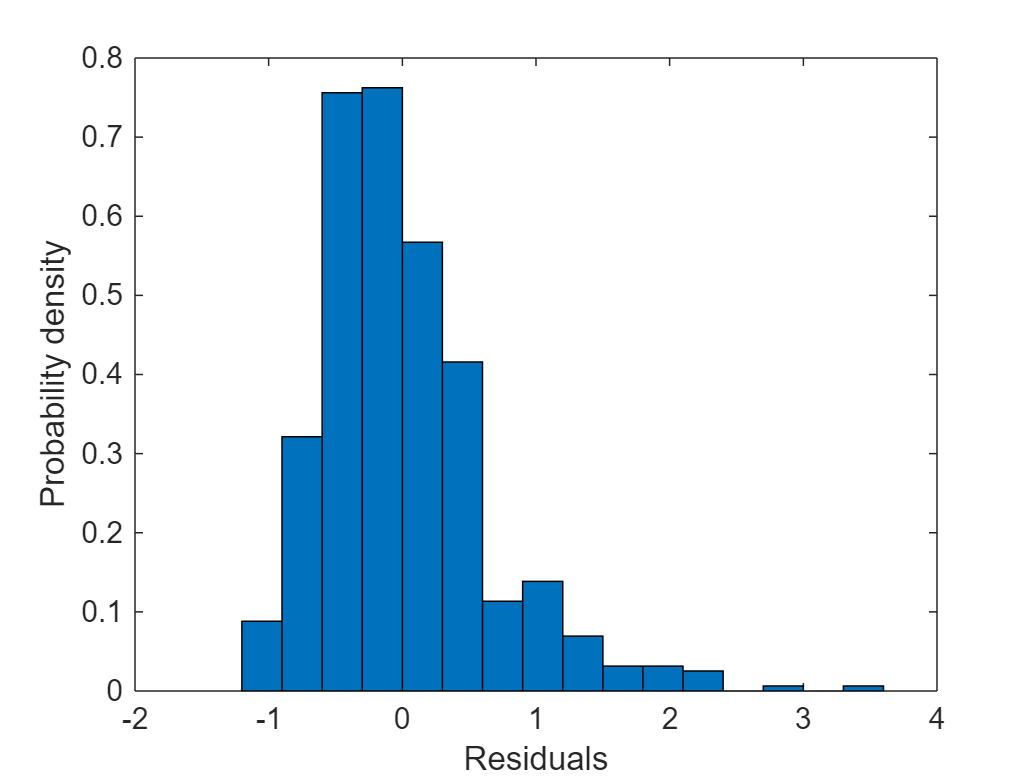

plotResiduals(mdl);
title("");

mdl_std = fitlm(X_std, y, 'VarNames', [total_predictors, data.Properties.VariableNames(end)]);
disp(mdl_std);


Linear regression model:
    Vertical_Velocity ~ 1 + Age + Sex_M + Body_Mass_Avg_Imput + Fall_Direction_forward + Fall_Direction_sideways + Cause_Of_Fall_C + Cause_Of_Fall_IT + Cause_Of_Fall_T + Activity_At_Time_Of_Fall_T

Estimated Coefficients:
                                  Estimate        SE        tStat        pValue   
                                  _________    ________    ________    ___________

    (Intercept)                       1.506    0.047174      31.925    1.5485e-124
    Age                            -0.78136    0.040636     -19.228     1.2985e-62
    Sex_M                           0.18763    0.073468       2.554       0.010935
    Body_Mass_Avg_Imput            -0.23958    0.035277     -6.7916     3.0449e-11
    Fall_Direction_forward      

% plotResiduals(mdl_std);

disp(mdl.ModelCriterion.AIC);

   1.0276e+03



disp(mdl.ModelCriterion.BIC);

   1.0704e+03



disp(mdl.MSE);

    0.4009



disp(mdl_std.ModelCriterion.AIC);

   1.0276e+03



disp(mdl_std.ModelCriterion.BIC);

   1.0704e+03



disp(mdl_std.MSE);

    0.4009



mdl_interacts = fitlm(X_interacts, y, 'VarNames', [total_predictors_interacts, data.Properties.VariableNames(end)]);

disp(mdl_interacts);


Linear regression model:
    Vertical_Velocity ~ 1 + Age + Sex_M + Body_Mass_Avg_Imput + Fall_Direction_forward + Fall_Direction_sideways + Cause_Of_Fall_C + Cause_Of_Fall_IT + Cause_Of_Fall_T + Activity_At_Time_Of_Fall_T + Sex_M:Fall_Direction_forward + Sex_M:Fall_Direction_sideways + Sex_M:Cause_Of_Fall_C + Sex_M:Cause_Of_Fall_T + Fall_Direction_forward:Fall_Direction_sideways + Fall_Direction_forward:Activity_At_Time_Of_Fall_T + Fall_Direction_sideways:Cause_Of_Fall_C + Fall_Direction_sideways:Cause_Of_Fall_IT + Fall_Direction_sideways:Cause_Of_Fall_T + Fall_Direction_sideways:Activity_At_Time_Of_Fall_T + Cause_Of_Fall_C:Cause_Of_Fall_IT + Cause_Of_Fall_C:Cause_Of_Fall_T + Cause_Of_Fall_C:Activity_At_Time_Of_Fall_T + Cause_Of_Fall_IT:Cause_Of_Fall_T + Cause_Of_Fall_T:Activity_At_Time_Of_Fall_T

Estimated Coefficients:
                                                           Estimate        SE          tStat        pValue<

% plotResiduals(mdl_interacts);
disp(mdl_interacts.ModelCriterion.AIC);

   1.0040e+03



disp(mdl_interacts.ModelCriterion.BIC);

   1.1108e+03



disp(mdl_interacts.MSE);

    0.3658



% mdl_interacts = fitlm(X_interacts_std, y, 'VarNames', [total_predictors_interacts, data.Properties.VariableNames(end)]);
% disp(mdl_interacts);
% plotResiduals(mdl_interacts);
% AIC_interacts = mdl_interacts.ModelCriterion.AIC;
% BIC_interacts = mdl_interacts.ModelCriterion.BIC;
% disp(AIC_interacts);
% disp(BIC_interacts);

nonzero_predictors = mdl_interacts.Coefficients.Estimate ~= 0;
nonzero_predictors = nonzero_predictors(2:end);
predictors = mdl_interacts.Coefficients.Properties.RowNames(2:end);
mdl_interacts_predictors = predictors(nonzero_predictors);
X_interacts_fitlm = X_interacts(:, nonzero_predictors);

mdl_quad = fitlm(X_quad, y, 'VarNames', [total_predictors_quad, data.Properties.VariableNames(end)]);

disp(mdl_quad);


Linear regression model:
    Vertical_Velocity ~ 1 + Age + Sex_M + Body_Mass_Avg_Imput + Fall_Direction_forward + Fall_Direction_sideways + Cause_Of_Fall_C + Cause_Of_Fall_IT + Cause_Of_Fall_T + Activity_At_Time_Of_Fall_T + Sex_M:Fall_Direction_forward + Sex_M:Fall_Direction_sideways + Sex_M:Cause_Of_Fall_C + Sex_M:Cause_Of_Fall_T + Fall_Direction_forward:Fall_Direction_sideways + Fall_Direction_forward:Activity_At_Time_Of_Fall_T + Fall_Direction_sideways:Cause_Of_Fall_C + Fall_Direction_sideways:Cause_Of_Fall_IT + Fall_Direction_sideways:Cause_Of_Fall_T + Fall_Direction_sideways:Activity_At_Time_Of_Fall_T + Cause_Of_Fall_C:Cause_Of_Fall_IT + Cause_Of_Fall_C:Cause_Of_Fall_T + Cause_Of_Fall_C:Activity_At_Time_Of_Fall_T + Cause_Of_Fall_IT:Cause_Of_Fall_T + Cause_Of_Fall_T:Activity_At_Time_Of_Fall_T

Estimated Coefficients:
                                                           Estimate        SE          tStat        pValue<

% plotResiduals(mdl_quad);
AIC = mdl_quad.ModelCriterion.AIC;
BIC = mdl_quad.ModelCriterion.BIC;
disp(AIC);

   1.0040e+03



disp(BIC);

   1.1108e+03



% mdl_quad_std = fitlm(X_quad_std, y, 'VarNames', [total_predictors_quad, data.Properties.VariableNames(end)]);
% disp(mdl_quad_std);
% plotResiduals(mdl_quad_std);
% AIC_quad = mdl_quad_std.ModelCriterion.AIC;
% BIC_quad = mdl_quad_std.ModelCriterion.BIC;
% disp(AIC_quad);
% disp(BIC_quad);

nonzero_predictors = mdl_quad.Coefficients.Estimate ~= 0;
nonzero_predictors = nonzero_predictors(2:end);
predictors = mdl_quad.Coefficients.Properties.RowNames(2:end);
mdl_quad_predictors = predictors(nonzero_predictors);
X_quad_fitlm = X_quad(:, nonzero_predictors);

% [B, FitInfo] = lasso(X_std, log(y), 'Standardize', false, 'CV', 10, "PredictorNames", total_predictors);
% lambdaMinMSE = FitInfo.LambdaMinMSE;
% lambda1SE = FitInfo.Lambda1SE;
% [B_lin_MinMSE, FitInfo_lin_MinMSE] = lasso(X_std, log(y), 'Lambda', lambdaMinMSE, "PredictorNames", total_predictors);
% [B_lin_sparse, FitInfo_lin_sparse] = lasso(X_std, log(y), 'Lambda', lambda1SE, "PredictorNames", total_predictors);
% MinMSEModelPredictors = FitInfo_lin_MinMSE.PredictorNames(B_lin_MinMSE ~=0);
% sparseModelPredictors = FitInfo_lin_sparse.PredictorNames(B_lin_sparse ~=0);
% [present, idx] = ismember(MinMSEModelPredictors, total_predictors);
% idx(idx == 0) = [];
% X_MinMSE = X(:, idx);
% [present, idx] = ismember(sparseModelPredictors, total_predictors);
% idx(idx == 0) = [];
% X_sparse = X(:, idx);

[B, FitInfo] = lasso(X_std, y, 'Standardize', false, 'CV', 10, "PredictorNames", total_predictors);
lambdaMinMSE = FitInfo.LambdaMinMSE;
lambda1SE = FitInfo.Lambda1SE;
[B_lin_MinMSE, FitInfo_lin_MinMSE] = lasso(X_std, y, 'Lambda', lambdaMinMSE, "PredictorNames", total_predictors);
[B_lin_sparse, FitInfo_lin_sparse] = lasso(X_std, y, 'Lambda', lambda1SE, "PredictorNames", total_predictors);
MinMSEModelPredictors = FitInfo_lin_MinMSE.PredictorNames(B_lin_MinMSE ~=0);
sparseModelPredictors = FitInfo_lin_sparse.PredictorNames(B_lin_sparse ~=0);
[present, idx] = ismember(MinMSEModelPredictors, total_predictors);
idx(idx == 0) = [];
X_MinMSE = X(:, idx);
[present, idx] = ismember(sparseModelPredictors, total_predictors);
idx(idx == 0) = [];
X_sparse = X(:, idx);

[B, FitInfo] = lasso(X_interacts_std, y, 'Standardize', false, 'CV', 10, "PredictorNames", total_predictors_interacts);
lambdaMinMSE_interacts = FitInfo.LambdaMinMSE;
lambda1SE_interacts = FitInfo.Lambda1SE;
[B_interacts_MinMSE, FitInfo_interacts_MinMSE] = lasso(X_interacts_std, y, 'Lambda', lambdaMinMSE_interacts, "PredictorNames", total_predictors_interacts);
[B_interacts_sparse, FitInfo_interacts_sparse] = lasso(X_interacts_std, y, 'Lambda', lambda1SE_interacts, "PredictorNames", total_predictors_interacts);
MinMSEModelPredictors_interacts = FitInfo_interacts_MinMSE.PredictorNames(B_interacts_MinMSE ~=0);
sparseModelPredictors_interacts = FitInfo_interacts_sparse.PredictorNames(B_interacts_sparse ~=0);
[present, idx] = ismember(MinMSEModelPredictors_interacts, total_predictors_interacts);
idx(idx == 0) = [];
X_MinMSE_interacts = X_interacts(:, idx);
[present, idx] = ismember(sparseModelPredictors_interacts, total_predictors_interacts);
idx(idx == 0) = [];
X_sparse_interacts = X_interacts(:, idx);

[B, FitInfo] = lasso(X_quad_std, y, 'Standardize', false, 'CV', 10, "PredictorNames", total_predictors_quad);
lambdaMinMSE_quad = FitInfo.LambdaMinMSE;
lambda1SE_quad = FitInfo.Lambda1SE;
[B_quad_MinMSE, FitInfo_quad_MinMSE] = lasso(X_quad_std, y, 'Lambda', lambdaMinMSE_quad, "PredictorNames", total_predictors_quad);
[B_quad_sparse, FitInfo_quad_sparse] = lasso(X_quad_std, y, 'Lambda', lambda1SE_quad, "PredictorNames", total_predictors_quad);
MinMSEModelPredictors_quad = FitInfo_quad_MinMSE.PredictorNames(B_quad_MinMSE ~=0);
sparseModelPredictors_quad = FitInfo_quad_sparse.PredictorNames(B_quad_sparse ~=0);
[present, idx] = ismember(MinMSEModelPredictors_quad, total_predictors_quad);
idx(idx == 0) = [];
X_MinMSE_quad = X_quad(:, idx);
[present, idx] = ismember(sparseModelPredictors_quad, total_predictors_quad);
idx(idx == 0) = [];
X_sparse_quad = X_quad(:, idx);

mdl_MinMSE = fitlm(X_MinMSE, y, 'VarNames', [MinMSEModelPredictors, data.Properties.VariableNames(end)]);
disp(mdl_MinMSE);


Linear regression model:
    Vertical_Velocity ~ 1 + Age + Sex_M + Body_Mass_Avg_Imput + Fall_Direction_forward + Fall_Direction_sideways + Cause_Of_Fall_C + Cause_Of_Fall_IT + Cause_Of_Fall_T + Activity_At_Time_Of_Fall_T

Estimated Coefficients:
                                  Estimate        SE         tStat        pValue  
                                  _________    _________    ________    __________

    (Intercept)                       4.207      0.19463      21.615    2.2728e-74
    Age                           -0.030486    0.0015854     -19.228    1.2985e-62
    Sex_M                           0.18763     0.073468       2.554      0.010935
    Body_Mass_Avg_Imput           -0.018586    0.0027366     -6.7916    3.0449e-11
    Fall_Direction_forward      

% plotResiduals(mdl_MinMSE);
AIC_MinMSE = mdl_MinMSE.ModelCriterion.AIC;
BIC_MinMSE = mdl_MinMSE.ModelCriterion.BIC;
disp(AIC_MinMSE);

   1.0276e+03



disp(BIC_MinMSE);

   1.0704e+03



% mdl_MinMSE_log = fitlm(X_MinMSE, log(y), 'VarNames', [MinMSEModelPredictors, data.Properties.VariableNames(end)]);
% disp(mdl_MinMSE_log);
% AIC_MinMSE_log = mdl_MinMSE_log.ModelCriterion.AIC;
% BIC_MinMSE_log = mdl_MinMSE_log.ModelCriterion.BIC;
% disp(AIC_MinMSE_log);
% disp(BIC_MinMSE_log);

% nonzero_predictors = mdl_MinMSE.Coefficients.Estimate ~= 0;
% nonzero_predictors = nonzero_predictors(2:end);
% predictors = mdl_MinMSE.Coefficients.Properties.RowNames(2:end);
% mdl_MinMSE_predictors = predictors(nonzero_predictors);
% X_MinMSE_fitlm = X_MinMSE(:, nonzero_predictors);

mdl_sparse = fitlm(X_sparse, y, 'VarNames', [sparseModelPredictors, data.Properties.VariableNames(end)]);
disp(mdl_sparse);


Linear regression model:
    Vertical_Velocity ~ 1 + Age + Body_Mass_Avg_Imput + Fall_Direction_forward + Fall_Direction_sideways + Activity_At_Time_Of_Fall_T

Estimated Coefficients:
                                  Estimate        SE         tStat       pValue  
                                  _________    _________    _______    __________

    (Intercept)                      3.9647       0.1719     23.063    1.0154e-81
    Age                           -0.029822    0.0015982     -18.66    6.1287e-60
    Body_Mass_Avg_Imput            -0.01491    0.0022931     -6.502    1.8528e-10
    Fall_Direction_forward         -0.72554     0.090897     -7.982    9.1851e-15
    Fall_Direction_sideways        0.041093     0.090004    0.45657       0.64817
    Activit

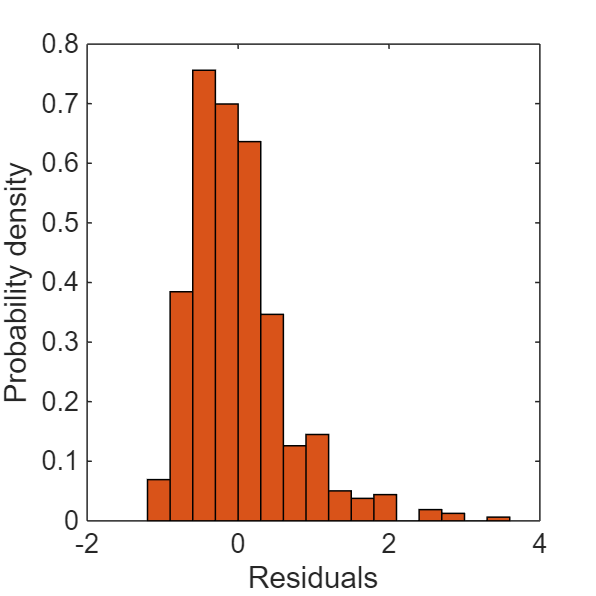

plotResiduals(mdl_sparse);
title("");

AIC_sparse = mdl_sparse.ModelCriterion.AIC;
BIC_sparse = mdl_sparse.ModelCriterion.BIC;
disp(AIC_sparse);

   1.0384e+03



disp(BIC_sparse);

   1.0640e+03



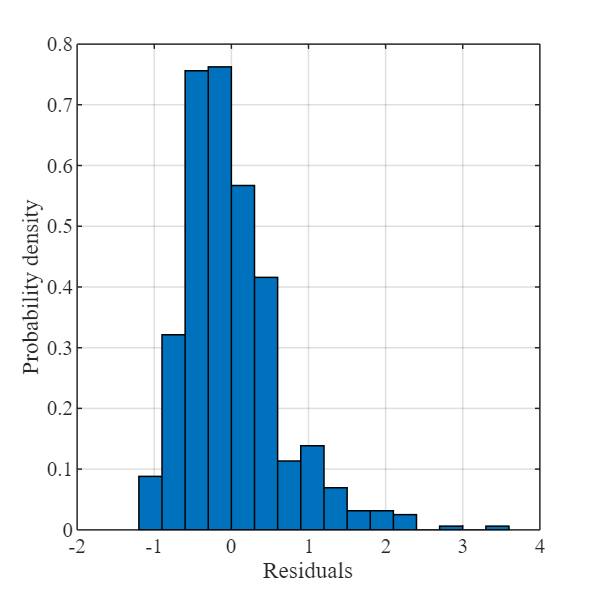

fig_width = 70/25.4;
fig_height = 70/25.4;
font = 'Times New Roman';
font_size = 7;
cb_color = [0.0000, 0.4470, 0.7410];

fig1 = figure('Units','inches','Position', [1, 1, fig_width, fig_height]);
h1 = plotResiduals(mdl);
set(h1(1), 'MarkerEdgeColor', cb_color, 'MarkerFaceColor', cb_color, ...
           'MarkerSize', 4);
xlabel('Residuals', 'FontName', font, 'FontSize', font_size);
ylabel('Probability density', 'FontName', font, 'FontSize', font_size);
title('');
set(gca, 'FontName', font, 'FontSize', font_size);
box on; grid on;
print(fig1, 'fig2a', '-depsc2', '-r1000');

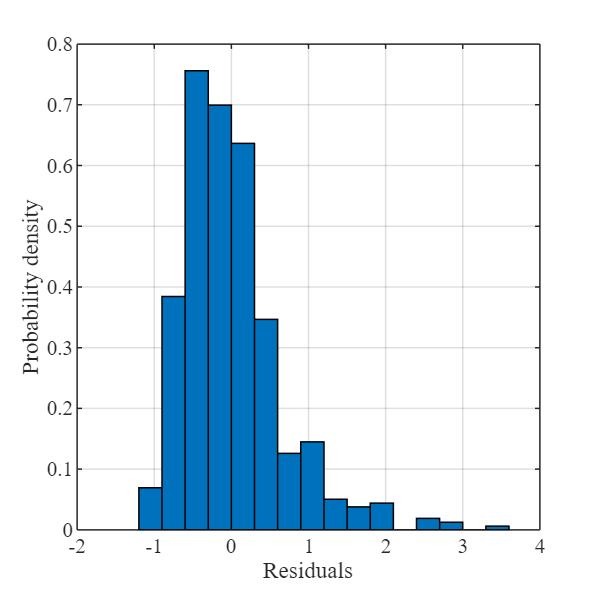


fig2 = figure('Units','inches','Position',[1, 1, fig_width, fig_height]);
h2 = plotResiduals(mdl_sparse);
set(h2(1), 'MarkerEdgeColor', cb_color, 'MarkerFaceColor', cb_color, ...
           'MarkerSize', 4);
xlabel('Residuals', 'FontName', font, 'FontSize', font_size);
ylabel('Probability density', 'FontName', font, 'FontSize', font_size);
title('');
set(gca, 'FontName', font, 'FontSize', font_size);
box on; grid on;
print(fig2, 'fig2b', '-depsc2', '-r1000');

% mdl_sparse_log = fitlm(X_sparse, log(y), 'VarNames', [sparseModelPredictors, data.Properties.VariableNames(end)]);
% disp(mdl_sparse_log);
% AIC_sparse_log = mdl_sparse_log.ModelCriterion.AIC;
% BIC_sparse_log = mdl_sparse_log.ModelCriterion.BIC;
% disp(AIC_sparse_log);
% disp(BIC_sparse_log);

% nonzero_predictors = mdl_sparse.Coefficients.Estimate ~= 0;
% nonzero_predictors = nonzero_predictors(2:end);
% predictors = mdl_sparse.Coefficients.Properties.RowNames(2:end);
% mdl_sparse_predictors = predictors(nonzero_predictors);
% X_sparse_fitlm = X_sparse(:, nonzero_predictors);

mdl_MinMSE_interacts = fitlm(X_MinMSE_interacts, y, 'VarNames', [MinMSEModelPredictors_interacts, data.Properties.VariableNames(end)]);
disp(mdl_MinMSE_interacts);


Linear regression model:
    Vertical_Velocity ~ 1 + Age + Sex_M + Body_Mass_Avg_Imput + Fall_Direction_forward + Fall_Direction_sideways + Cause_Of_Fall_C + Cause_Of_Fall_IT + Cause_Of_Fall_T + Activity_At_Time_Of_Fall_T + Sex_M:Fall_Direction_sideways + Sex_M:Cause_Of_Fall_C + Sex_M:Cause_Of_Fall_T + Fall_Direction_sideways:Cause_Of_Fall_C

Estimated Coefficients:
                                                Estimate        SE          tStat        pValue  
                                               __________    _________    _________    __________

    (Intercept)                                    4.1921      0.19061       21.993    4.3702e-76
    Age                                         -0.031873    0.0015301       -20.83    2.3591e-70
    Sex_M                                         

% plotResiduals(mdl_MinMSE_interacts);
AIC_MinMSE_interacts = mdl_MinMSE_interacts.ModelCriterion.AIC;
BIC_MinMSE_interacts = mdl_MinMSE_interacts.ModelCriterion.BIC;
disp(AIC_MinMSE_interacts);

  982.0148



disp(BIC_MinMSE_interacts);

   1.0418e+03



nonzero_predictors = mdl_MinMSE_interacts.Coefficients.Estimate ~= 0;
nonzero_predictors = nonzero_predictors(2:end);
predictors = mdl_MinMSE_interacts.Coefficients.Properties.RowNames(2:end);
mdl_MinMSE_interacts_predictors = predictors(nonzero_predictors);
X_MinMSE_interacts_fitlm = X_MinMSE_interacts(:, nonzero_predictors);

mdl_sparse_interacts = fitlm(X_sparse_interacts, y, 'VarNames', [sparseModelPredictors_interacts, data.Properties.VariableNames(end)]);
disp(mdl_sparse_interacts);


Linear regression model:
    Vertical_Velocity ~ 1 + Age + Sex_M + Body_Mass_Avg_Imput + Fall_Direction_forward + Fall_Direction_sideways + Cause_Of_Fall_C + Cause_Of_Fall_IT + Cause_Of_Fall_T + Activity_At_Time_Of_Fall_T + Sex_M:Cause_Of_Fall_T + Fall_Direction_sideways:Cause_Of_Fall_C

Estimated Coefficients:
                                               Estimate        SE         tStat       pValue  
                                               _________    _________    _______    __________

    (Intercept)                                   4.1818      0.18762     22.289    1.2586e-77
    Age                                        -0.031859    0.0015237    -20.909    8.2655e-71
    Sex_M                                        0.21925     0.074641     2.9374      0.003457
    Body_Mass_A

% plotResiduals(mdl_sparse_interacts);
AIC_sparse_interacts = mdl_sparse_interacts.ModelCriterion.AIC;
BIC_sparse_interacts = mdl_sparse_interacts.ModelCriterion.BIC;
disp(AIC_sparse_interacts);

  978.1282



disp(BIC_sparse_interacts);

   1.0294e+03



nonzero_predictors = mdl_sparse_interacts.Coefficients.Estimate ~= 0;
nonzero_predictors = nonzero_predictors(2:end);
predictors = mdl_sparse_interacts.Coefficients.Properties.RowNames(2:end);
mdl_sparse_interacts_predictors = predictors(nonzero_predictors);
X_sparse_interacts_fitlm = X_sparse_interacts(:, nonzero_predictors);

mdl_MinMSE_quad = fitlm(X_MinMSE_quad, y, 'VarNames', [MinMSEModelPredictors_quad, data.Properties.VariableNames(end)]);
disp(mdl_MinMSE_quad);


Linear regression model:
    Vertical_Velocity ~ 1 + Age + Sex_M + Body_Mass_Avg_Imput + Fall_Direction_forward + Fall_Direction_sideways + Cause_Of_Fall_C + Cause_Of_Fall_IT + Cause_Of_Fall_T + Activity_At_Time_Of_Fall_T + Sex_M:Cause_Of_Fall_C + Sex_M:Cause_Of_Fall_T + Fall_Direction_sideways:Cause_Of_Fall_C

Estimated Coefficients:
                                               Estimate        SE         tStat        pValue  
                                               _________    _________    ________    __________

    (Intercept)                                   4.1921      0.19043      22.015    3.1168e-76
    Age                                        -0.031878    0.0015261     -20.888    1.1252e-70
    Sex_M                                        0.22923     0.080671      2.8415     0.00

% plotResiduals(mdl_MinMSE_quad);
AIC_MinMSE_quad = mdl_MinMSE_quad.ModelCriterion.AIC;
BIC_MinMSE_quad = mdl_MinMSE_quad.ModelCriterion.BIC;
disp(AIC_MinMSE_quad);

  980.0181



disp(BIC_MinMSE_quad);

   1.0355e+03



nonzero_predictors = mdl_MinMSE_quad.Coefficients.Estimate ~= 0;
nonzero_predictors = nonzero_predictors(2:end);
predictors = mdl_MinMSE_quad.Coefficients.Properties.RowNames(2:end);
mdl_MinMSE_quad_predictors = predictors(nonzero_predictors);
X_MinMSE_quad_fitlm = X_MinMSE_quad(:, nonzero_predictors);

mdl_sparse_quad = fitlm(X_sparse_quad, y, 'VarNames', [sparseModelPredictors_quad, data.Properties.VariableNames(end)]);
disp(mdl_sparse_quad);


Linear regression model:
    Vertical_Velocity ~ 1 + Age + Sex_M + Body_Mass_Avg_Imput + Fall_Direction_forward + Fall_Direction_sideways + Cause_Of_Fall_C + Cause_Of_Fall_IT + Cause_Of_Fall_T + Activity_At_Time_Of_Fall_T + Sex_M:Cause_Of_Fall_T + Fall_Direction_sideways:Cause_Of_Fall_C

Estimated Coefficients:
                                               Estimate        SE         tStat       pValue  
                                               _________    _________    _______    __________

    (Intercept)                                   4.1818      0.18762     22.289    1.2586e-77
    Age                                        -0.031859    0.0015237    -20.909    8.2655e-71
    Sex_M                                        0.21925     0.074641     2.9374      0.003457
    Body_Mass_A

% plotResiduals(mdl_sparse_quad);
AIC_sparse_quad = mdl_sparse_quad.ModelCriterion.AIC;
BIC_sparse_quad = mdl_sparse_quad.ModelCriterion.BIC;
disp(AIC_sparse_quad);

  978.1282



disp(BIC_sparse_quad);

   1.0294e+03



nonzero_predictors = mdl_sparse_quad.Coefficients.Estimate ~= 0;
nonzero_predictors = nonzero_predictors(2:end);
predictors = mdl_sparse_quad.Coefficients.Properties.RowNames(2:end);
mdl_sparse_quad_predictors = predictors(nonzero_predictors);
X_sparse_quad_fitlm = X_sparse_quad(:, nonzero_predictors);

function [VIF, best_VIF_predictors, best_VIFs] = get_VIF(X, total_predictors)
    VIF = diag(inv(corrcoef(X)));

    VIF_idx = VIF > 1 & VIF < 5;
    best_VIF_predictors = total_predictors(VIF_idx);
    best_VIF_predictors = best_VIF_predictors(:)';
    best_VIFs = VIF(VIF_idx);

    fprintf('Acceptable VIF:\n');
    for i = 1:length(total_predictors)
        fprintf('%s: %.4f\n', total_predictors{i}, VIF(i));
    end

    disp(length(total_predictors) - length(best_VIF_predictors));

    % fprintf('VIF:\n');
    % for i = 1:length(total_predictors)
    %     fprintf('%s: %.4f\n', total_predictors{i}, VIF(i));
    % end
end

[VIF, best_VIF_predictors, best_VIF] = get_VIF(X, total_predictors);

Acceptable VIF:
Age: 2.1746
Sex_M: 1.5944
Body_Mass_Avg_Imput: 1.6389
Fall_Direction_forward: 4.3170
Fall_Direction_sideways: 1.7085
Cause_Of_Fall_C: 1.5271
Cause_Of_Fall_IT: 1.9694
Cause_Of_Fall_T: 2.1858
Activity_At_Time_Of_Fall_T: 1.0574
     0



% [VIF_interacts, best_VIF_interacts_predictors, best_VIF_interacts] = get_VIF(X_interacts, total_predictors_interacts);
% [VIF_quad, best_VIF_quad_predictors, best_VIF_quad] = get_VIF(X_quad, total_predictors_quad);
[VIF_interacts_fitlm, best_VIF_interacts_fitlm_predictors, best_VIF_interacts_fitlm] = get_VIF(X_interacts_fitlm, mdl_interacts_predictors);

Acceptable VIF:
Age: 2.2251
Sex_M: 3.3588
Body_Mass_Avg_Imput: 1.9048
Fall_Direction_forward: 7.3628
Fall_Direction_sideways: 2.2260
Cause_Of_Fall_C: 4.0919
Cause_Of_Fall_IT: 2.3207
Cause_Of_Fall_T: 4.1287
Activity_At_Time_Of_Fall_T: 1.0672
Sex_M:Fall_Direction_forward: 4.7080
Sex_M:Fall_Direction_sideways: 2.0606
Sex_M:Cause_Of_Fall_C: 2.6070
Sex_M:Cause_Of_Fall_T: 3.0535
Fall_Direction_sideways:Cause_Of_Fall_C: 2.1516
     1



[VIF_quad_fitlm, best_VIF_quad_fitlm_predictors, best_VIF_quad_fitlm] = get_VIF(X_quad_fitlm, mdl_quad_predictors);

Acceptable VIF:
Age: 2.2251
Sex_M: 3.3588
Body_Mass_Avg_Imput: 1.9048
Fall_Direction_forward: 7.3628
Fall_Direction_sideways: 2.2260
Cause_Of_Fall_C: 4.0919
Cause_Of_Fall_IT: 2.3207
Cause_Of_Fall_T: 4.1287
Activity_At_Time_Of_Fall_T: 1.0672
Sex_M:Fall_Direction_forward: 4.7080
Sex_M:Fall_Direction_sideways: 2.0606
Sex_M:Cause_Of_Fall_C: 2.6070
Sex_M:Cause_Of_Fall_T: 3.0535
Fall_Direction_sideways:Cause_Of_Fall_C: 2.1516
     1



[VIF_MinMSE, best_VIF_MinMSE_predictors, best_VIF_MinMSE] = get_VIF(X_MinMSE, MinMSEModelPredictors);

Acceptable VIF:
Age: 2.1746
Sex_M: 1.5944
Body_Mass_Avg_Imput: 1.6389
Fall_Direction_forward: 4.3170
Fall_Direction_sideways: 1.7085
Cause_Of_Fall_C: 1.5271
Cause_Of_Fall_IT: 1.9694
Cause_Of_Fall_T: 2.1858
Activity_At_Time_Of_Fall_T: 1.0574
     0



[VIF_sparse, best_VIF_sparse_predictors, best_VIF_sparse] = get_VIF(X_sparse, sparseModelPredictors);

Acceptable VIF:
Age: 2.1493
Body_Mass_Avg_Imput: 1.1193
Fall_Direction_forward: 1.9654
Fall_Direction_sideways: 1.6181
Activity_At_Time_Of_Fall_T: 1.0095
     0



[VIF_MinMSE_interacts, best_VIF_MinMSE_interacts_predictors, best_VIF_MinMSE_interacts] = get_VIF(X_MinMSE_interacts, MinMSEModelPredictors_interacts);

Acceptable VIF:
Age: 2.2244
Sex_M: 2.4419
Body_Mass_Avg_Imput: 1.7564
Fall_Direction_forward: 5.4600
Fall_Direction_sideways: 2.2045
Cause_Of_Fall_C: 3.8349
Cause_Of_Fall_IT: 2.3099
Cause_Of_Fall_T: 3.5623
Activity_At_Time_Of_Fall_T: 1.0659
Sex_M:Fall_Direction_sideways: 1.8073
Sex_M:Cause_Of_Fall_C: 2.2549
Sex_M:Cause_Of_Fall_T: 2.1979
Fall_Direction_sideways:Cause_Of_Fall_C: 2.1425
     1



[VIF_sparse_interacts, best_VIF_sparse_interacts_predictors, best_VIF_sparse_interacts] = get_VIF(X_sparse_interacts, sparseModelPredictors_interacts);

Acceptable VIF:
Age: 2.2139
Sex_M: 1.8139
Body_Mass_Avg_Imput: 1.6871
Fall_Direction_forward: 5.4464
Fall_Direction_sideways: 1.7777
Cause_Of_Fall_C: 2.8059
Cause_Of_Fall_IT: 2.3055
Cause_Of_Fall_T: 3.5314
Activity_At_Time_Of_Fall_T: 1.0646
Sex_M:Cause_Of_Fall_T: 2.1026
Fall_Direction_sideways:Cause_Of_Fall_C: 2.1080
     1



[VIF_MinMSE_quad, best_VIF_MinMSE_quad_predictors, best_VIF_MinMSE_quad] = get_VIF(X_MinMSE_quad, MinMSEModelPredictors_quad);

Acceptable VIF:
Age: 2.2170
Sex_M: 2.1152
Body_Mass_Avg_Imput: 1.7486
Fall_Direction_forward: 5.4597
Fall_Direction_sideways: 1.7861
Cause_Of_Fall_C: 3.8208
Cause_Of_Fall_IT: 2.3072
Cause_Of_Fall_T: 3.5464
Activity_At_Time_Of_Fall_T: 1.0650
Sex_M:Cause_Of_Fall_C: 2.2400
Sex_M:Cause_Of_Fall_T: 2.1467
Fall_Direction_sideways:Cause_Of_Fall_C: 2.1080
     1



[VIF_sparse_quad, best_VIF_sparse_quad_predictors, best_VIF_sparse_quad] = get_VIF(X_sparse_quad, sparseModelPredictors_quad);

Acceptable VIF:
Age: 2.2139
Sex_M: 1.8139
Body_Mass_Avg_Imput: 1.6871
Fall_Direction_forward: 5.4464
Fall_Direction_sideways: 1.7777
Cause_Of_Fall_C: 2.8059
Cause_Of_Fall_IT: 2.3055
Cause_Of_Fall_T: 3.5314
Activity_At_Time_Of_Fall_T: 1.0646
Sex_M:Cause_Of_Fall_T: 2.1026
Fall_Direction_sideways:Cause_Of_Fall_C: 2.1080
     1



[VIF_MinMSE_interacts_fitlm, best_VIF_MinMSE_interacts_fitlm_predictors, best_VIF_MinMSE_interacts_fitlm] = get_VIF(X_MinMSE_interacts_fitlm, mdl_MinMSE_interacts_predictors);

Acceptable VIF:
Age: 2.2244
Sex_M: 2.4419
Body_Mass_Avg_Imput: 1.7564
Fall_Direction_forward: 5.4600
Fall_Direction_sideways: 2.2045
Cause_Of_Fall_C: 3.8349
Cause_Of_Fall_IT: 2.3099
Cause_Of_Fall_T: 3.5623
Activity_At_Time_Of_Fall_T: 1.0659
Sex_M:Fall_Direction_sideways: 1.8073
Sex_M:Cause_Of_Fall_C: 2.2549
Sex_M:Cause_Of_Fall_T: 2.1979
Fall_Direction_sideways:Cause_Of_Fall_C: 2.1425
     1



[VIF_sparse_interacts_fitlm, best_VIF_sparse_interacts_fitlm_predictors, best_VIF_sparse_interacts_fitlm] = get_VIF(X_sparse_interacts_fitlm, mdl_sparse_interacts_predictors);

Acceptable VIF:
Age: 2.2139
Sex_M: 1.8139
Body_Mass_Avg_Imput: 1.6871
Fall_Direction_forward: 5.4464
Fall_Direction_sideways: 1.7777
Cause_Of_Fall_C: 2.8059
Cause_Of_Fall_IT: 2.3055
Cause_Of_Fall_T: 3.5314
Activity_At_Time_Of_Fall_T: 1.0646
Sex_M:Cause_Of_Fall_T: 2.1026
Fall_Direction_sideways:Cause_Of_Fall_C: 2.1080
     1



function errors = regf_lasso(XTrain, yTrain, XTest, yTest)
    predictors = strcat("Var", string(1:size(XTrain, 2)));  
    tbltrain = array2table(XTrain, 'VariableNames', predictors);
    tbltrain.Response = yTrain;

    tbltest = array2table(XTest, 'VariableNames', predictors);
    tbltest.Response = yTest;

    mdl = fitlm(tbltrain);

    yfit = predict(mdl, tbltest);
    MAE = mean(abs(yfit - tbltest.Response));
    adjMAE = MAE / range(tbltest.Response);
    
    errors = [MAE adjMAE];
end

rng('default')
MAE = crossval(@(XTrain, yTrain, XTest, yTest) regf_lasso(XTrain, yTrain, XTest, yTest), X, y)

MAE =     0.4406    0.1459
    0.4982    0.1650
    0.5207    0.1724
    0.4923    0.1630
    0.5238    0.1622
    0.4471    0.1480
    0.4850    0.1606
    0.3792    0.1256
    0.5660    0.1874
    0.4285    0.1419


MAE_MinMSE = crossval(@(XTrain, yTrain, XTest, yTest) regf_lasso(XTrain, yTrain, XTest, yTest), X_MinMSE, y)

MAE_MinMSE =     0.4495    0.1489
    0.4008    0.1327
    0.4485    0.1389
    0.4973    0.1609
    0.5443    0.1802
    0.4613    0.1527
    0.5320    0.1761
    0.5052    0.1673
    0.3967    0.1314
    0.5500    0.1821


MAE_sparse = crossval(@(XTrain, yTrain, XTest, yTest) regf_lasso(XTrain, yTrain, XTest, yTest), X_sparse, y)

MAE_sparse =     0.5551    0.1719
    0.4918    0.1628
    0.4352    0.1441
    0.5369    0.1778
    0.4481    0.1484
    0.4993    0.1653
    0.3781    0.1252
    0.5235    0.1734
    0.4061    0.1521
    0.4634    0.1500


disp(mean(MAE));

    0.4781    0.1572



disp(mean(MAE_MinMSE));

    0.4786    0.1571



disp(mean(MAE_sparse));

    0.4737    0.1571



disp("Linear model adjusted R-squared: " + mdl.Rsquared.Adjusted);

Linear model adjusted R-squared: 0.59071


disp("Linear model MSE: " + mdl.MSE);

Linear model MSE: 0.40093


disp("Linear model MAE: " + mean(MAE(:, 1)));

Linear model MAE: 0.47814


disp("Linear model AIC: " + mdl.ModelCriterion.AIC);

Linear model AIC: 1027.648


disp("Linear model BIC: " + mdl.ModelCriterion.BIC);

Linear model BIC: 1070.3579


disp("Linear model (minMSE) adjusted R-squared: " + mdl_MinMSE.Rsquared.Adjusted);

Linear model (minMSE) adjusted R-squared: 0.59071


disp("Linear model (minMSE) MSE: " + mdl_MinMSE.MSE);

Linear model (minMSE) MSE: 0.40093


disp("Linear model (minMSE) MAE: " + mean(MAE_MinMSE(:, 1)));

Linear model (minMSE) MAE: 0.47857


disp("Linear model (minMSE) AIC: " + mdl_MinMSE.ModelCriterion.AIC);

Linear model (minMSE) AIC: 1027.648


disp("Linear model (minMSE) BIC: " + mdl_MinMSE.ModelCriterion.BIC);

Linear model (minMSE) BIC: 1070.3579


disp("Linear model (sparse) adjusted R-squared: " + mdl_sparse.Rsquared.Adjusted);

Linear model (sparse) adjusted R-squared: 0.57921


disp("Linear model (sparse) MSE: " + mdl_sparse.MSE);

Linear model (sparse) MSE: 0.41219


disp("Linear model (sparse) MAE: " + mean(MAE_sparse(:, 1)));

Linear model (sparse) MAE: 0.47374


disp("Linear model (sparse) AIC: " + mdl_sparse.ModelCriterion.AIC);

Linear model (sparse) AIC: 1038.3647


disp("Linear model (sparse) BIC: " + mdl_sparse.ModelCriterion.BIC);

Linear model (sparse) BIC: 1063.9907


% disp("Quadratic model (sparse) adjusted R-squared: " + mdl_sparse_quad.Rsquared.Adjusted);
% disp("Quadratic model (sparse) MSE: " + mdl_sparse_quad.MSE);
% disp("Quadratic model (sparse) MAE: " + mean(MAE_sparse_quad(:, 1)));
% disp("Quadratic model (sparse) AIC: " + mdl_sparse_quad.ModelCriterion.AIC);
% disp("Quadratic model (sparse) BIC: " + mdl_sparse_quad.ModelCriterion.BIC);

lin_str = 'Linear model';
lin_MinMSE_str = 'Linear model w/ MinMSE predictors';
lin_sparse_str = 'Linear model w/ sparse predictors';
adjR2_col = [
    mdl.Rsquared.Adjusted;
    mdl_MinMSE.Rsquared.Adjusted;
    mdl_sparse.Rsquared.Adjusted
];
MSE_col = [
    mdl.MSE;
    mdl_MinMSE.MSE;
    mdl_sparse.MSE
];
MAE_col = [
    mean(MAE(:, 1));
    mean(MAE_MinMSE(:, 1));
    mean(MAE_sparse(:, 1))
];
AIC_col = [
    mdl.ModelCriterion.AIC;
    mdl_MinMSE.ModelCriterion.AIC;
    mdl_sparse.ModelCriterion.AIC
];
BIC_col = [
    mdl.ModelCriterion.BIC;
    mdl_MinMSE.ModelCriterion.BIC;
    mdl_sparse.ModelCriterion.BIC
];
metrics_mdl = table(round(adjR2_col, 2), round(MSE_col, 2), round(MAE_col, 2), AIC_col, BIC_col, 'VariableNames', {'Adjusted R2', 'MSE', 'MAE', 'AIC', 'BIC'}, 'RowNames', {lin_str, lin_MinMSE_str, lin_sparse_str});
disp(metrics_mdl);

                                         Adjusted R2    MSE     MAE      AIC       BIC  
                                         ___________    ____    ____    ______    ______

    Linear model                            0.59         0.4    0.48    1027.6    1070.4
    Linear model w/ MinMSE predictors       0.59         0.4    0.48    1027.6    1070.4
    Linear model w/ sparse predictors       0.58        0.41    0.47    1038.4      1064



writetable(metrics_mdl, 'coefficent_tables.xlsx', 'Sheet', 'Sheet1');

ci_mdl = coefCI(mdl);
coefs_mdl = mdl.Coefficients;
effects_mdl = table(round(coefs_mdl.Estimate, 3), round(coefs_mdl.SE, 3), round(ci_mdl(:,1), 3), round(ci_mdl(:,2), 3), round(coefs_mdl.pValue, 3), 'VariableNames', {'Regression Coefficient', 'SE', '95% CI Lower', '95% CI Upper', 'p-value'}, 'RowNames', coefs_mdl.Properties.RowNames);
disp(effects_mdl);

                                  Regression Coefficient     SE      95% CI Lower    95% CI Upper    p-value
                                  ______________________    _____    ____________    ____________    _______

    (Intercept)                            4.207            0.195        3.825           4.589            0 
    Age                                    -0.03            0.002       -0.034          -0.027            0 
    Sex_M                                  0.188            0.073        0.043           0.332        0.011 
    Body_Mass_Avg_Imput                   -0.019            0.003       -0.024          -0.013            0 
    Fall_Direction_forward                 -1.07            0.133       -1.331          -0

writetable(effects_mdl, 'coefficent_tables.xlsx', 'Sheet', 'Sheet2');

% figure;
% 
% errorbar(1:length(coefs_mdl.Estimate), coefs_mdl.Estimate, coefs_mdl.Estimate - ci_mdl(:,1), ci_mdl(:,2) - coefs_mdl.Estimate, 'o', ...
%     'MarkerFaceColor','b','Color','k','CapSize',6);
% 
% xticks(1:length(mdl.CoefficientNames));
% xticklabels({'(Constant)', 'A', 'S', 'M', 'Dir_F', 'Dir_S', 'Cause_C', 'Cause_{IT}', 'Cause_T', 'T'});
% xtickangle(45);
% xlim([0, length(coefs_mdl.Estimate) + 1]);
% ylabel('Coefficient Estimate');
% grid on;
% box on;

ci_mdl_MinMSE = coefCI(mdl_MinMSE);
coefs_mdl_MinMSE = mdl_MinMSE.Coefficients;
effects_mdl_MinMSE = table(round(coefs_mdl_MinMSE.Estimate, 3), round(coefs_mdl_MinMSE.SE, 3), round(ci_mdl_MinMSE(:,1), 3), round(ci_mdl_MinMSE(:,2), 3), round(coefs_mdl_MinMSE.pValue, 3), 'VariableNames', {'Regression Coefficient', 'SE', '95% CI Lower', '95% CI Upper', 'p-value'}, 'RowNames', coefs_mdl_MinMSE.Properties.RowNames);
disp(effects_mdl_MinMSE);

                                  Regression Coefficient     SE      95% CI Lower    95% CI Upper    p-value
                                  ______________________    _____    ____________    ____________    _______

    (Intercept)                            4.207            0.195        3.825           4.589            0 
    Age                                    -0.03            0.002       -0.034          -0.027            0 
    Sex_M                                  0.188            0.073        0.043           0.332        0.011 
    Body_Mass_Avg_Imput                   -0.019            0.003       -0.024          -0.013            0 
    Fall_Direction_forward                 -1.07            0.133       -1.331          -0

writetable(effects_mdl_MinMSE, 'coefficent_tables.xlsx', 'Sheet', 'Sheet3');

% figure;
% 
% errorbar(1:length(coefs_mdl_MinMSE.Estimate), coefs_mdl_MinMSE.Estimate, coefs_mdl_MinMSE.Estimate - ci_mdl_MinMSE(:,1), ci_mdl_MinMSE(:,2) - coefs_mdl_MinMSE.Estimate, 'o', ...
%     'MarkerFaceColor','b','Color','k','CapSize',6);
% 
% xticks(1:length(mdl_MinMSE.CoefficientNames));
% xticklabels({'(Constant)', 'A', 'S', 'M', 'Dir_F', 'Dir_S', 'Cause_C', 'Cause_{IT}', 'Cause_T', 'T'});
% xtickangle(45);
% xlim([0, length(coefs_mdl_MinMSE.Estimate) + 1]);
% ylabel('Coefficient Estimate');
% grid on;
% box on;

ci_mdl_sparse = coefCI(mdl_sparse);
coefs_mdl_sparse = mdl_sparse.Coefficients;
effects_mdl_sparse = table(round(coefs_mdl_sparse.Estimate, 3), round(coefs_mdl_sparse.SE, 3), round(ci_mdl_sparse(:,1), 3), round(ci_mdl_sparse(:,2), 3), round(coefs_mdl_sparse.pValue, 3), 'VariableNames', {'Regression Coefficient', 'SE', '95% CI Lower', '95% CI Upper', 'p-value'}, 'RowNames', coefs_mdl_sparse.Properties.RowNames);
disp(effects_mdl_sparse);

                                  Regression Coefficient     SE      95% CI Lower    95% CI Upper    p-value
                                  ______________________    _____    ____________    ____________    _______

    (Intercept)                            3.965            0.172        3.627           4.302            0 
    Age                                    -0.03            0.002       -0.033          -0.027            0 
    Body_Mass_Avg_Imput                   -0.015            0.002       -0.019           -0.01            0 
    Fall_Direction_forward                -0.726            0.091       -0.904          -0.547            0 
    Fall_Direction_sideways                0.041             0.09       -0.136           0

writetable(effects_mdl_sparse, 'coefficent_tables.xlsx', 'Sheet', 'Sheet4');

% figure;
% errorbar(1:length(coefs_mdl_sparse.Estimate), coefs_mdl_sparse.Estimate, coefs_mdl_sparse.Estimate - ci_mdl_sparse(:,1), ci_mdl_sparse(:,2) - coefs_mdl_sparse.Estimate, 'o', ...
%     'MarkerFaceColor','b','Color','k','CapSize',6);
% 
% xticks(1:length(mdl_sparse.CoefficientNames));
% xticklabels({'(Constant)', 'A', 'M', 'Dir_F', 'Dir_S', 'T'});
% xtickangle(45);
% xlim([0.5, length(coefs_mdl_sparse.Estimate) + 0.5]);
% ylabel('Coefficient Estimate');
% grid on;
% box on;

fig_width = 70/25.4;
fig_height = 70/25.4;

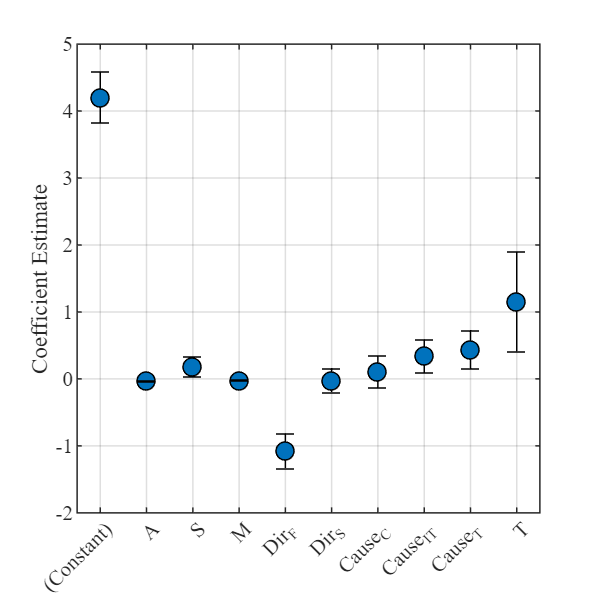

fig1 = figure('Units','inches','Position',[1, 1, fig_width, fig_height]);
xticks_mdl = {'(Constant)', 'A', 'S', 'M', 'Dir_F', 'Dir_S', 'Cause_C', 'Cause_{IT}', 'Cause_T', 'T'};
xticks_sparse = {'(Constant)', 'A', 'M', 'Dir_F', 'Dir_S', 'T'};

errorbar(1:length(coefs_mdl.Estimate), coefs_mdl.Estimate, ...
    coefs_mdl.Estimate - ci_mdl(:,1), ci_mdl(:,2) - coefs_mdl.Estimate, ...
    'o', 'MarkerFaceColor', cb_color, 'Color', 'k', 'CapSize', 6);
xticks(1:length(xticks_mdl));
xticklabels(xticks_mdl);
xtickangle(45);
xlim([0.5, length(coefs_mdl.Estimate) + 0.5]);
ylabel('Coefficient Estimate', 'FontName', font, 'FontSize', font_size);
set(gca, 'FontName', font, 'FontSize', font_size);
grid on;
box on;
print(fig1, 'fig1a', '-depsc2', '-r1000');

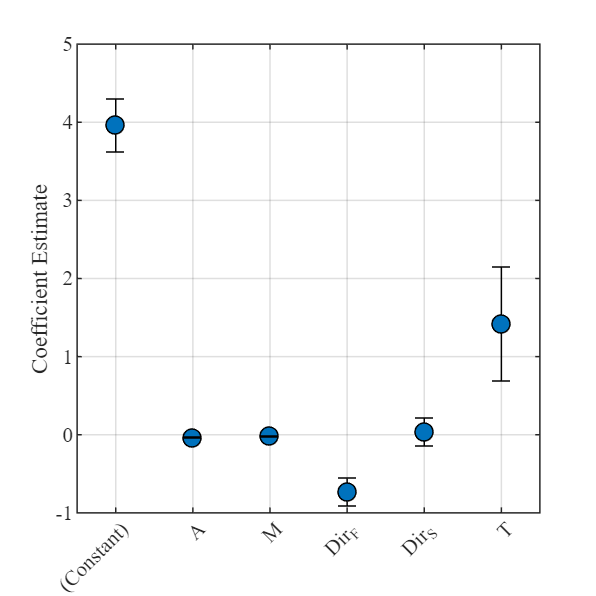


fig2 = figure('Units','inches','Position',[1, 1, fig_width, fig_height]);
errorbar(1:length(coefs_mdl_sparse.Estimate), coefs_mdl_sparse.Estimate, ...
    coefs_mdl_sparse.Estimate - ci_mdl_sparse(:,1), ci_mdl_sparse(:,2) - coefs_mdl_sparse.Estimate, ...
    'o', 'MarkerFaceColor', cb_color, 'Color', 'k', 'CapSize', 6);
xticks(1:length(xticks_sparse));
xticklabels(xticks_sparse);
xtickangle(45);
xlim([0.5, length(coefs_mdl_sparse.Estimate) + 0.5]);
ylabel('Coefficient Estimate', 'FontName', font, 'FontSize', font_size);
set(gca, 'FontName', font, 'FontSize', font_size);
grid on;
box on;
print(fig2, 'fig1b', '-depsc2', '-r1000');

% mdl = fitlm(data);


Linear regression model:
    Vertical_Velocity ~ 1 + Age + Sex + Body_Mass_Avg_Imput + Height_Avg_Imput + Fall_Direction + Cause_Of_Fall + Activity_At_Time_Of_Fall

Estimated Coefficients:
                                  Estimate        SE         tStat        pValue  
                                  _________    _________    ________    __________

    (Intercept)                      2.3255      0.91728      2.5352      0.011531
    Age                           -0.030048    0.0015663     -19.184    2.7442e-62
    Sex_M                           0.11882     0.066901       1.776      0.076323
    Body_Mass_Avg_Imput           -0.032966    0.0040258     -8.1887    2.0948e-15
    Height_Avg_Imput                 2.8178      0.50952      5.5304    5.0891e-08
    

  883.2384



  943.0322



% disp(mdl);
% plotResiduals(mdl);
% AIC_lin = mdl.ModelCriterion.AIC;
% BIC_lin = mdl.ModelCriterion.BIC;
% disp(AIC_lin);
% disp(BIC_lin);

% mdl_interacts = fitlm(data, "interactions");
% disp(mdl_interacts);
% plotResiduals(mdl_interacts);
% AIC_interacts = mdl_interacts.ModelCriterion.AIC;
% BIC_interacts = mdl_interacts.ModelCriterion.BIC;
% disp(AIC_interacts);
% disp(BIC_interacts);

% nonzero_predictors = mdl_interacts.Coefficients.Estimate ~= 0;
% mdl_interacts_predictors = mdl_interacts.Coefficients.Properties.RowNames(nonzero_predictors);
% X_interacts_fitlm = X_interacts(:, nonzero_predictors(2:end));

% mdl_quad = fitlm(data, "quadratic");
% disp(mdl_quad);
% plotResiduals(mdl_quad);
% AIC_quad = mdl_quad.ModelCriterion.AIC;
% BIC_quad = mdl_quad.ModelCriterion.BIC;
% disp(AIC_quad);
% disp(BIC_quad);

% nonzero_predictors = mdl_quad.Coefficients.Estimate ~= 0;
% mdl_quad_predictors = mdl_quad.Coefficients.Properties.RowNames(nonzero_predictors);
% X_quad_fitlm = X_quad(:, nonzero_predictors(2:end));

% function cvR2 = crossvalR2(X, y)
%     cv = cvpartition(length(y), 'KFold', 10);
%     cvR2_arr = zeros(cv.NumTestSets, 1);
% 
%     for i = 1:cv.NumTestSets
%         train_idx = cv.training(i);
%         test_idx = cv.test(i);
% 
%         X_train = X(train_idx, :);
%         y_train = y(train_idx);
%         X_test  = X(test_idx, :);
%         y_test  = y(test_idx);
% 
%         mdl = fitlm(X_train, y_train);
%         y_pred = predict(mdl, X_test);
% 
%         rss = sum((y_test - y_pred).^2);
%         tss = sum((y_test - mean(y_test)).^2);
%         cvR2_arr(i) = 1 - (rss / tss);
%     end
% 
%     cvR2 = mean(cvR2_arr);
% end

% function [R2_cv, AIC, BIC] = lasso_metrics(X, y, lambda)
% 
%     [B, FitInfo] = lasso(X, y, 'Standardize', false, 'Lambda', lambda, 'CV', 10);
% 
%     y_pred = X * B + FitInfo.Intercept;
% 
%     y_mean = mean(y);
%     SST = sum((y - y_mean).^2);
% 
%     [~, idx] = min(abs(FitInfo.Lambda - lambda));
% 
%     if isfield(FitInfo, 'MSE')
%         cvMSE = FitInfo.MSE(idx);
%         R2_cv = 1 - (cvMSE / (SST / length(y)));
%     else
%         R2_cv = NaN;
%     end
% 
%     RSS = sum((y - y_pred).^2);
%     n = length(y);
%     k = sum(B ~= 0) + 1;
% 
%     AIC = n * log(RSS / n) + 2 * k;
%     BIC = n * log(RSS / n) + log(n) * k;
% end

% cvR2 = crossvalR2(X_std, y)
% cvR2_interacts = crossvalR2(X_interacts_std, y)
% cvR2_quad = crossvalR2(X_quad_std, y)

% [cvR2_MinMSE, AIC_MinMSE, BIC_MinMSE] = lasso_metrics(X_std, y, lambdaMinMSE)
% [cvR2_sparse, AIC_sparse, BIC_sparse] = lasso_metrics(X_std, y, lambda1SE)
% [cvR2_interacts_MinMSE, AIC_interacts_MinMSE, BIC_interacts_MinMSE] = lasso_metrics(X_interacts_std, y, lambdaMinMSE_interacts)
% [cvR2_interacts_sparse, AIC_interacts_sparse, BIC_interacts_sparse] = lasso_metrics(X_interacts_std, y, lambda1SE_interacts)
% [cvR2_quad_MinMSE, AIC_quad_MinMSE, BIC_quad_MinMSE] = lasso_metrics(X_quad_std, y, lambdaMinMSE_quad)
% [cvR2_quad_sparse, AIC_quad_sparse, BIC_quad_sparse] = lasso_metrics(X_quad_std, y, lambda1SE_quad)

% function errors = regf(Age_train, Sex_train, Body_Mass_Avg_Imput_train, Height_Avg_Imput_train, Fall_Direction_train, Cause_Of_Fall_train, Activity_At_Time_Of_Fall_train, Vertical_Velocity_train, ...
%                        Age_test, Sex_test, Body_Mass_Avg_Imput_test, Height_Avg_Imput_test, Fall_Direction_test, Cause_Of_Fall_test, Activity_At_Time_Of_Fall_test, Vertical_Velocity_test)
% 
%     tbltrain = table(Age_train, Sex_train, Body_Mass_Avg_Imput_train, Height_Avg_Imput_train, Fall_Direction_train, Cause_Of_Fall_train, Activity_At_Time_Of_Fall_train, Vertical_Velocity_train, ...
%         'VariableNames', {'Age', 'Sex', 'Body_Mass_Avg_Imput', 'Height_Avg_Imput', 'Fall_Direction', 'Cause_Of_Fall', 'Activity_At_Time_Of_Fall', 'Vertical_Velocity'});
% 
%     tbltest = table(Age_test, Sex_test, Body_Mass_Avg_Imput_test, Height_Avg_Imput_test, Fall_Direction_test, Cause_Of_Fall_test, Activity_At_Time_Of_Fall_test, Vertical_Velocity_test, ...
%         'VariableNames', {'Age', 'Sex', 'Body_Mass_Avg_Imput', 'Height_Avg_Imput', 'Fall_Direction', 'Cause_Of_Fall', 'Activity_At_Time_Of_Fall', 'Vertical_Velocity'});
% 
%     mdl = fitlm(tbltrain);
% 
%     yfit = predict(mdl, tbltest);
% 
%     MAE = mean(abs(yfit - tbltest.Vertical_Velocity));
% 
%     adjMAE = MAE / range(tbltest.Vertical_Velocity);
% 
%     errors = [MAE adjMAE];
% end

% function [coefs_MinMSE_table, coefs_sparse_table] = lasso_bootstrap(X, y, lambdaMinMSE, lambda1SE, predictors)
%     n = size(X, 1);
%     n_bstrap = 1000;
% 
%     coefs_MinMSE = zeros(size(X, 2), n_bstrap);
%     coefs_sparse = zeros(size(X, 2), n_bstrap);
% 
%     intercepts_MinMSE = zeros(n_bstrap, 1);
%     intercepts_sparse = zeros(n_bstrap, 1);
% 
%     for i = 1:n_bstrap
%         idx = randsample(n, n, true);
%         X_b = X(idx, :);
%         y_b = y(idx);
% 
%         [B_MinMSE, FitInfo_MinMSE] = lasso(X_b, y_b, 'Standardize', false, 'Lambda', lambdaMinMSE);
%         coefs_MinMSE(:, i) = B_MinMSE;
%         intercepts_MinMSE(i) = FitInfo_MinMSE.Intercept;
% 
% 
%         [B_sparse, FitInfo_sparse] = lasso(X_b, y_b, 'Standardize', false, 'Lambda', lambda1SE);
%         coefs_sparse(:, i) = B_sparse;
%         intercepts_sparse(i) = FitInfo_sparse.Intercept;
%     end
% 
%     coefs_MinMSE_mean = mean(coefs_MinMSE, 2);
%     coefs_MinMSE_sd = std(coefs_MinMSE, 0, 2);
%     coefs_MinMSE_ci = prctile(coefs_MinMSE, [2.5, 97.5], 2);
%     coefs_MinMSE_selection_freq = mean(coefs_MinMSE ~= 0, 2);
% 
%     coefs_sparse_mean = mean(coefs_sparse, 2);
%     coefs_sparse_sd = std(coefs_sparse, 0, 2);
%     coefs_sparse_ci = prctile(coefs_sparse, [2.5, 97.5], 2);
%     coefs_sparse_selection_freq = mean(coefs_sparse ~= 0, 2);
% 
%     coefs_MinMSE_table = table(...
%         coefs_MinMSE_mean(B_MinMSE ~= 0), coefs_MinMSE_sd(B_MinMSE ~= 0), ...
%         coefs_MinMSE_ci(B_MinMSE ~= 0, 1), coefs_MinMSE_ci(B_MinMSE ~= 0, 2), coefs_MinMSE_selection_freq(B_MinMSE ~= 0), ...
%         'VariableNames', {'Mean', 'SE', '95% CI Lower', '95% CI Upper', 'Selection Frequency'}, ...
%         'RowNames', predictors(B_MinMSE ~= 0));
% 
%     coefs_sparse_table = table(...
%         coefs_sparse_mean(B_sparse ~= 0), coefs_sparse_sd(B_sparse ~= 0), ...
%         coefs_sparse_ci(B_sparse ~= 0, 1), coefs_sparse_ci(B_sparse ~= 0, 2), coefs_sparse_selection_freq(B_sparse ~= 0), ...
%         'VariableNames', {'Mean', 'SE', '95% CI Lower', '95% CI Upper', 'Selection Frequency'}, ...
%         'RowNames', predictors(B_sparse ~= 0));
% end

% filename = "C:\Users\holzb\Downloads\Impact Velocity Data.xlsx";
% sheets = {"Choi et al 2015", "Robinovitch et al 2004", "Robinovitch et al 2003", ...
%           "Hsiao & Robinovitch 1998", "Wang et al 2017", "Smeesters et al 2001", "Michaels et al 2025", "Khorami et al 2023"};
% cols_choi = ["Faller_ID", "Age", "Age_Min", "Age_Max", "Age_Mean", "Age_SD", "Sex", "Body_Mass", ...
%              "Body_Mass_Mean", "Body_Mass_SD", "Body_Mass_MC", "Body_Mass_Hot_Deck", "Body_Mass_Anthro", ...
%              "Body_Mass_Avg_Imput", "Height_Avg_Imput", "Height_Mean", "Height_SD", "Height_MC", ...
%              "Fall_Direction", "Cause_Of_Fall", "Activity_At_Time_Of_Fall", "Horizontal_Velocity", ...
%              "Vertical_Velocity", "Random_Seed", "Var25", "Var26"];
% cols_rob04 = ["Faller_ID", "Age", "Age_Min", "Age_Max", "Age_Mean", "Age_SD", "Sex", "Body_Mass_Min", ...
%              "Body_Mass_Max", "Body_Mass_Mean", "Body_Mass_SD", "Body_Mass_MC", "Body_Mass_Anthro", ...
%              "Body_Mass_Avg_Imput", "Height_Min", "Height_Max", "Height_Mean", "Height_SD", "Height_MC", ...
%              "Height_Anthro", "Height_Avg_Imput", "Fall_Direction", "Cause_Of_Fall", "Activity_At_Time_Of_Fall", ...
%              "Horizontal_Velocity", "Vertical_Velocity", "Random_Seed", "Var25", "Var26"];
% cols_rob03 = ["Faller_ID", "Age", "Age_Min", "Age_Max", "Age_Mean", "Age_SD", "Sex", "Body_Mass_Min", ...
%              "Body_Mass_Max", "Body_Mass_Mean", "Body_Mass_SD", "Body_Mass_MC", "Body_Mass_Anthro", ...
%              "Body_Mass_Avg_Imput", "Height_Min", "Height_Max", "Height_Mean", "Height_SD", "Height_MC", ...
%              "Height_Anthro", "Height_Avg_Imput", "Fall_Direction", "Cause_Of_Fall", "Activity_At_Time_Of_Fall", ...
%              "Horizontal_Velocity", "Vertical_Velocity", "Random_Seed", "Var25", "Var26"];
% cols_hrob = ["Faller_ID", "Age", "Age_Min", "Age_Max", "Age_Mean", "Age_SD", "Sex", "Body_Mass_Min", ...
%              "Body_Mass_Max", "Body_Mass_Mean", "Body_Mass_SD", "Body_Mass_MC", "Body_Mass_Anthro", ...
%              "Body_Mass_Avg_Imput", "Height_Min", "Height_Max", "Height_Mean", "Height_SD", "Height_MC", ...
%              "Height_Anthro", "Height_Avg_Imput", "Fall_Direction", "Cause_Of_Fall", "Activity_At_Time_Of_Fall", ...
%              "Horizontal_Velocity", "Vertical_Velocity", "Random_Seed", "Var25", "Var26"];
% cols_wang = ["Faller_ID", "Age", "Age_Min", "Age_Mean", "Age_SD", "Sex", "Body_Mass_Mean", "Body_Mass_SD", ...
%              "Body_Mass_MC", "Body_Mass_Anthro", "Body_Mass_Avg_Imput", "Height_Mean", "Height_SD", ...
%              "Height_MC", "Height_Anthro", "Height_Avg_Imput", "Fall_Direction", "Cause_Of_Fall", ...
%              "Activity_At_Time_Of_Fall", "Horizontal_Velocity", "Vertical_Velocity", "Random_Seed", "Var25", "Var26"];
% cols_smeesters = ["Faller_ID", "Age", "Age_Min", "Age_Max", "Age_Mean", "Age_SD", "Sex", "Body_Mass_Mean", "Body_Mass_SD", ...
%                   "Body_Mass_MC", "Body_Mass_Anthro", "Body_Mass_Avg_Imput", "Height_Mean", "Height_SD", "Height_MC", ...
%                   "Height_Anthro", "Height_Avg_Imput", "Fall_Direction", "Cause_Of_Fall", "Activity_At_Time_Of_Fall", ...
%                   "Horizontal_Velocity", "Vertical_Velocity", "Random_Seed", "Var25", "Var26"];
% cols_michaels = ["Faller_ID", "Age", "Age_Min", "Age_Max", "Age_Mean", "Age_SD", "Sex", "Body_Mass_Mean", "Body_Mass_SD", ...
%                   "Body_Mass_MC", "Body_Mass_Anthro", "Body_Mass_Avg_Imput", "Height_Mean", "Height_SD", "Height_MC", ...
%                   "Height_Anthro", "Height_Avg_Imput", "Fall_Direction", "Cause_Of_Fall", "Activity_At_Time_Of_Fall", ...
%                   "Horizontal_Velocity", "Vertical_Velocity", "Random_Seed", "Var25", "Var26"];
% cols_khorami = ["Faller_ID", "Age", "Sex", "Body_Mass_Avg_Imput", "Height_Avg_Imput", "Fall_Direction", "Cause_Of_Fall", "Activity_At_Time_Of_Fall", "Horizontal_Velocity", "Vertical_Velocity", "Var25", "Var26"];
% 
% cols = {cols_choi, cols_rob04, cols_rob03, cols_hrob, cols_wang, cols_smeesters, cols_michaels, cols_khorami};
% 
% filter_cols = {["Faller_ID", "Age", "Age_Min", "Age_Max", "Age_Mean", "Age_SD", "Sex", "Body_Mass_Mean", "Body_Mass_SD", ...
%                 "Body_Mass_Avg_Imput", "Height_Mean", "Height_SD", "Height_Avg_Imput", "Fall_Direction", ...
%                 "Cause_Of_Fall", "Activity_At_Time_Of_Fall", "Horizontal_Velocity", "Vertical_Velocity"], ...
%                ["Faller_ID", "Age", "Age_Min", "Age_Max", "Age_Mean", "Age_SD", "Sex", "Body_Mass_Min", ...
%                 "Body_Mass_Max", "Body_Mass_Mean", "Body_Mass_SD", "Body_Mass_Avg_Imput", "Height_Min", ...
%                 "Height_Max", "Height_Mean", "Height_SD", "Height_Avg_Imput", "Fall_Direction", "Cause_Of_Fall", ...
%                 "Activity_At_Time_Of_Fall", "Horizontal_Velocity", "Vertical_Velocity"], ...
%                ["Faller_ID", "Age", "Age_Min", "Age_Max", "Age_Mean", "Age_SD", "Sex", "Body_Mass_Min", ...
%                 "Body_Mass_Max", "Body_Mass_Mean", "Body_Mass_SD", "Body_Mass_Avg_Imput", "Height_Min", ...
%                 "Height_Max", "Height_Mean", "Height_SD", "Height_Avg_Imput", "Fall_Direction", "Cause_Of_Fall", ...
%                 "Activity_At_Time_Of_Fall", "Horizontal_Velocity", "Vertical_Velocity"], ...
%                ["Faller_ID", "Age", "Age_Min", "Age_Max", "Age_Mean", "Age_SD", "Sex", "Body_Mass_Min", ...
%                 "Body_Mass_Max", "Body_Mass_Mean", "Body_Mass_SD", "Body_Mass_Avg_Imput", "Height_Min", ...
%                 "Height_Max", "Height_Mean", "Height_SD", "Height_Avg_Imput", "Fall_Direction", "Cause_Of_Fall", ...
%                 "Activity_At_Time_Of_Fall", "Horizontal_Velocity", "Vertical_Velocity"], ...
%                ["Faller_ID", "Age", "Age_Min", "Age_Mean", "Age_SD", "Sex", "Body_Mass_Mean", "Body_Mass_SD", "Body_Mass_Avg_Imput", ...
%                 "Height_Mean", "Height_SD", "Height_Avg_Imput", "Fall_Direction", "Cause_Of_Fall", ...
%                 "Activity_At_Time_Of_Fall", "Horizontal_Velocity", "Vertical_Velocity"], ...
%                ["Faller_ID", "Age", "Age_Min", "Age_Max", "Age_Mean", "Age_SD", "Sex", "Body_Mass_Mean", "Body_Mass_SD", "Body_Mass_Avg_Imput", ...
%                 "Height_Mean", "Height_SD", "Height_Avg_Imput", "Fall_Direction", "Cause_Of_Fall", ...
%                 "Activity_At_Time_Of_Fall", "Horizontal_Velocity", "Vertical_Velocity"], ...
%                ["Faller_ID", "Age", "Age_Min", "Age_Max", "Age_Mean", "Age_SD", "Sex", "Body_Mass_Mean", "Body_Mass_SD", "Body_Mass_Avg_Imput", ...
%                 "Height_Mean", "Height_SD", "Height_Avg_Imput", "Fall_Direction", "Cause_Of_Fall", ...
%                 "Activity_At_Time_Of_Fall", "Horizontal_Velocity", "Vertical_Velocity"], ...
%                 ["Faller_ID", "Age", "Sex", "Body_Mass_Avg_Imput", "Height_Avg_Imput", "Fall_Direction", "Cause_Of_Fall", ...
%                 "Activity_At_Time_Of_Fall", "Horizontal_Velocity", "Vertical_Velocity"]};
% 
% data = cell(1, length(sheets));
% 
% for i = 1:length(sheets)
%     all_data = readtable(filename, "Sheet", sheets{i});
%     all_data.Properties.VariableNames = cols{i};
%     available_cols = intersect(filter_cols{i}, all_data.Properties.VariableNames);
%     data{i} = all_data(:, available_cols);
% 
%     disp(["Sheet: " + sheets{i} + " | Columns Kept: " + strjoin(available_cols, ", ")]);
% end
% 
% wang = data{5};
% smeesters = data{6};
% michaels = data{7};
% khorami = data{8};
% 
% wang_split = wang(wang.Age_Mean == wang.Age_Mean(1), :);
% wang_feet = wang(wang.Age_Mean == wang.Age_Mean(110), :);
% 
% smeesters_female = smeesters(smeesters.Age_Max == smeesters.Age_Max(1), :);
% smeesters_male = smeesters(smeesters.Age_Max == smeesters.Age_Max(90), :);
% 
% data{5} = wang_split;
% data{6} = wang_feet;
% data{7} = smeesters_female;
% data{8} = smeesters_male;
% data{9} = michaels;
% data{10} = khorami;
% 
% 
% sheets = {"Choi et al 2015", "Robinovitch et al 2004", "Robinovitch et al 2003", ...
%           "Hsiao & Robinovitch 1998", "Wang et al 2017", "Wang et al 2017", ...
%           "Smeesters et al 2001", "Smeesters et al 2001", "Michaels et al 2025", "Khorami et al 2023"};

% Age Multiple Imputation
% num_subjects = length(unique(data{9}.Faller_ID));
% mean_val = data{9}.Age_Mean(1);
% sd_val = data{9}.Age_SD(1);
% min_val = data{9}.Age_Min(1);
% max_val = data{9}.Age_Max(1);
% 
% ages = floor(normrnd(mean_val, sd_val, [num_subjects, 1]));
% 
% if any(ages < min_val)
%     ages = max(ages, min_val);
% end
% 
% if any(ages > max_val)
%     ages = min(ages, max_val);
% end
% 
% while true
%     if mean(ages) >= mean_val && mean(ages) < mean_val + 1
%         if std(ages) >= sd_val && std(ages) < sd_val + 0.05
%             break;
%         end
%     end
%     ages = floor(normrnd(mean_val, sd_val, [num_subjects, 1]));
%     while any(ages < min_val)
%         ages = max(ages, min_val);
%     end
%     while any(ages > max_val)
%         ages = min(ages, max_val);
%     end
% end
% 
% final_mean = mean(ages);
% final_sd = std(ages);
% 
% disp(["Final Mean: ", num2str(final_mean)]);
% disp(["Final Standard Deviation: ", num2str(final_sd)]);
% 
% % Display generated ages
% disp(ages);

% age_mc_data = readmatrix("output_age_mc.xlsx");
% rob04_age_mc = age_mc_data(1, 1:23)';
% rob03_age_mc = age_mc_data(2, 1:22)';
% hrob_age_mc = age_mc_data(3, 1:6)';
% wang_split_age_mc = age_mc_data(4:108, 1);
% wang_feet_age_mc = age_mc_data(4:98, 2);
% smeesters_female_age_mc = age_mc_data(4, 3:9)';
% smeesters_male_age_mc = age_mc_data(5, 3:9)';
% michaels_age_mc = age_mc_data(4:16, 11);
% age_mc = {rob04_age_mc, rob03_age_mc, hrob_age_mc, wang_split_age_mc, wang_feet_age_mc, ...
%           smeesters_female_age_mc, smeesters_male_age_mc, michaels_age_mc};

% for i = 1:length(age_mc)
%     sheet = data{i+1};
%     subject_ids = unique(sheet.Faller_ID);
%     num_subjects = length(subject_ids);
%     all_subject_ages = cell(height(sheet), 1);
%     for j = 1:num_subjects
%         idx = sheet.Faller_ID == subject_ids(j);
%         all_subject_ages(idx) = {age_mc{i}(j)};
%     end
%     sheet.Age = cell2mat(all_subject_ages);
%     data{i+1} = sheet;
% end

% function num_decimals = count_decimals(value)
%     if mod(value, 1) == 0
%         num_decimals = 0;
%         return;
%     end
% 
%     str_val = sprintf("%.2f", value);
% 
%     str_val = strtrim(regexprep(str_val, "0+$", ""));
% 
%     decimal_pos = find(str_val == ".", 1);
% 
%     if isempty(decimal_pos)
%         num_decimals = 0;
%     else
%         num_decimals = length(str_val) - decimal_pos;
%     end
% end

% Body Mass Multiple Imputation function
% function bm_mc = bm_monte_carlo(mean_val, sd_val, num_subjects, min_val, max_val)
%     if nargin < 4
%         bm_mc = round(normrnd(mean_val, sd_val, [1, num_subjects]), 2);
% 
%         while true
%             curr_mean = mean(bm_mc);
%             curr_sd = std(bm_mc);
% 
%             if curr_mean >= mean_val - 0.5*10^(-count_decimals(mean_val)) && curr_mean < mean_val + 0.5*10^(-count_decimals(mean_val))
%                 if curr_sd >= sd_val - 0.5*10^(-count_decimals(sd_val)) && curr_sd < sd_val + 0.5*10^(-count_decimals(sd_val))
%                     break;
%                 end
%             end
% 
%             if curr_sd > 0
%                 bm_mc = round((bm_mc - curr_mean) * (sd_val / curr_sd) + mean_val, 2);
%             end
%         end
%     else
%         bm_mc = round(normrnd(mean_val, sd_val, [1, num_subjects]), 2);
% 
%         bm_mc = min(max(bm_mc, min_val), max_val);
% 
%         bm_mc = sort(bm_mc);
% 
%         bm_min_present = ismember(round(bm_mc, count_decimals(min_val)), min_val);
%         bm_max_present = ismember(round(bm_mc, count_decimals(max_val)), max_val);
% 
%         if ~any(bm_min_present) && ~any(bm_max_present)
%             bm_mc([1, end]) = [min_val, max_val];
%         elseif ~any(bm_min_present) && any(bm_max_present)
%             bm_mc(1) = min_val;
%         elseif ~any(bm_max_present) && any(bm_min_present)
%             bm_mc(end) = max_val;
%         end
% 
%         for i = 1:10
%             curr_mean = mean(bm_mc);
%             curr_sd = std(bm_mc);
%             if curr_mean >= mean_val - 0.5*10^(-count_decimals(mean_val)) && curr_mean < mean_val + 0.5*10^(-count_decimals(mean_val))
%                 if curr_sd >= sd_val - 0.5*10^(-count_decimals(sd_val)) && curr_sd < sd_val + 0.5*10^(-count_decimals(sd_val))
%                     break;
%                 end
%             end
% 
%             if curr_sd > 0
%                 bm_mc = round((bm_mc - curr_mean) * (sd_val / curr_sd) + mean_val, 2);
% 
%                 bm_mc = min(max(bm_mc, min_val), max_val);
% 
%                 bm_mc = sort(bm_mc);
% 
%                 bm_min_present = ismember(round(bm_mc, count_decimals(min_val)), min_val);
%                 bm_max_present = ismember(round(bm_mc, count_decimals(max_val)), max_val);
% 
%                 if ~any(bm_min_present) && ~any(bm_max_present)
%                     bm_mc([1, end]) = [min_val, max_val];
%                 elseif ~any(bm_min_present) && any(bm_max_present)
%                     bm_mc(1) = min_val;
%                 elseif ~any(bm_max_present) && any(bm_min_present)
%                         bm_mc(end) = max_val;
%                 end
%             end  
%         end
%     end
%     bm_mc = sort(bm_mc);
% end

% i = 10;
% sheet = data{i};
% subject_ids = unique(sheet.Faller_ID);
% num_subjects = length(subject_ids);

% bm_mean = sheet.Body_Mass_Mean(1);
% bm_sd = sheet.Body_Mass_SD(1);
% 
% if any(strcmp(sheets{i}, ["Robinovitch et al 2004", "Robinovitch et al 2003", "Hsiao & Robinovitch 1998"]))
%     bm_min = sheet.Body_Mass_Min(1);
%     bm_max = sheet.Body_Mass_Max(1);
%     bm_mc = bm_monte_carlo(bm_mean, bm_sd, num_subjects, bm_min, bm_max);
% else
%     bm_mc = bm_monte_carlo(bm_mean, bm_sd, num_subjects);
% end
% 
% all_bm_ages = cell(height(sheet), 1);
% 
% for j = 1:num_subjects
%     idx = sheet.Faller_ID == subject_ids(j);
%     all_bm_ages(idx) = {bm_mc(j)};
% end
% 
% sheet.Body_Mass_Avg_Imput = cell2mat(all_bm_ages);
% 
% data{i} = sheet;
% 
% disp(["Body Mass mean: " + sheets{i}]);
% bm_mean
% mean(bm_mc)
% disp(["Body Mass std dev: " + sheets{i}]);
% bm_sd
% std(bm_mc)

% Height Multiple Imputation function
% function height_mc = height_monte_carlo(mean_val, sd_val, num_subjects, min_val, max_val)
%     if nargin < 4
%         height_mc = round(normrnd(mean_val, sd_val, [1, num_subjects]), 2);
% 
%         for i = 1:10
%             curr_mean = mean(height_mc);
%             curr_sd = std(height_mc);
% 
%             if curr_mean >= mean_val - 0.5*10^(-count_decimals(mean_val)) && curr_mean < mean_val + 0.5*10^(-count_decimals(mean_val))
%                 if curr_sd >= sd_val - 0.5*10^(-count_decimals(sd_val)) && curr_sd < sd_val + 0.5*10^(-count_decimals(sd_val))
%                     break;
%                 end
%             end
% 
%             if curr_sd > 0
%                 height_mc = round((height_mc - curr_mean) * (sd_val / curr_sd) + mean_val, 2);
%             end
%         end
%     else
%         height_mc = round(normrnd(mean_val, sd_val, [1, num_subjects]), 2);
% 
%         height_mc = min(max(height_mc, min_val), max_val);
% 
%         height_mc = sort(height_mc);
% 
%         height_min_present = ismember(round(height_mc, count_decimals(min_val)), min_val);
%         height_max_present = ismember(round(height_mc, count_decimals(max_val)), max_val);
% 
%         if ~any(height_min_present) && ~any(height_max_present)
%             height_mc([1, end]) = [min_val, max_val];
%         elseif ~any(height_min_present) && any(height_max_present)
%             height_mc(1) = min_val;
%         elseif ~any(height_max_present) && any(height_min_present)
%             height_mc(end) = max_val;
%         end
% 
%         for i = 1:10
%             curr_mean = mean(height_mc);
%             curr_sd = std(height_mc);
% 
%             if curr_mean >= mean_val - 0.5*10^(-count_decimals(mean_val)) && curr_mean < mean_val + 0.5*10^(-count_decimals(mean_val))
%                 if curr_sd >= sd_val - 0.5*10^(-count_decimals(sd_val)) && curr_sd < sd_val + 0.5*10^(-count_decimals(sd_val))
%                     break;
%                 end
%             end
% 
%             if curr_sd > 0
%                 height_mc = round((height_mc - curr_mean) * (sd_val / curr_sd) + mean_val, 2);
% 
%                 height_mc = min(max(height_mc, min_val), max_val);
% 
%                 height_mc = sort(height_mc);
% 
%                 height_min_present = ismember(round(height_mc, count_decimals(min_val)), min_val);
%                 height_max_present = ismember(round(height_mc, count_decimals(max_val)), max_val);
% 
%                 if ~any(height_min_present) && ~any(height_max_present)
%                     height_mc([1, end]) = [min_val, max_val];
%                 elseif ~any(height_min_present) && any(height_max_present)
%                     height_mc(1) = min_val;
%                 elseif ~any(height_max_present) && any(height_min_present)
%                     height_mc(end) = max_val;
%                 end
%             end  
%         end
%     end
%     height_mc = sort(height_mc);
% end

% height_mean = sheet.Height_Mean(1)
% height_sd = sheet.Height_SD(1)
% 
% if any(strcmp(sheets{i}, ["Robinovitch et al 2004", "Robinovitch et al 2003", "Hsiao & Robinovitch 1998"]))
%     height_min = sheet.Height_Min(1);
%     height_max = sheet.Height_Max(1);
%     height_mc = height_monte_carlo(height_mean, height_sd, num_subjects, height_min, height_max);
% else
%     height_mc = height_monte_carlo(height_mean, height_sd, num_subjects);
% end
% 
% all_height_ages = cell(height(sheet), 1);
% 
% for j = 1:num_subjects
%     idx = sheet.Faller_ID == subject_ids(j);
%     all_height_ages(idx) = {height_mc(j)};
% end
% 
% sheet.Height_Avg_Imput = cell2mat(all_height_ages);
% 
% data{i} = sheet;
% 
% disp(["Height mean: " + sheets{i}]);
% height_mean
% mean(sheet.Height_Avg_Imput)
% disp(["Height std dev: " + sheets{i}]);
% height_sd
% std(sheet.Height_Avg_Imput)

% filter_col = ["Age", "Sex", "Body_Mass_Avg_Imput", "Height_Avg_Imput", "Fall_Direction", "Cause_Of_Fall", "Activity_At_Time_Of_Fall", "Vertical_Velocity"];
% for i = 1:length(sheets)
%     data{i} = data{i}(:, filter_col);
% end